Preprocessing the synthetic datasets and construct the between group matrix **W** and linkage matrix **C**

close all
clear all
clc

rng(213);
load('./Data/dot.mat');     % load the associated data file into work space
% Feature Matrix: X -- M x D     Y -- N x D
% Class Name: lx -- M x1     ly -- N x 1

Construct the Between Group relational matrix **W**

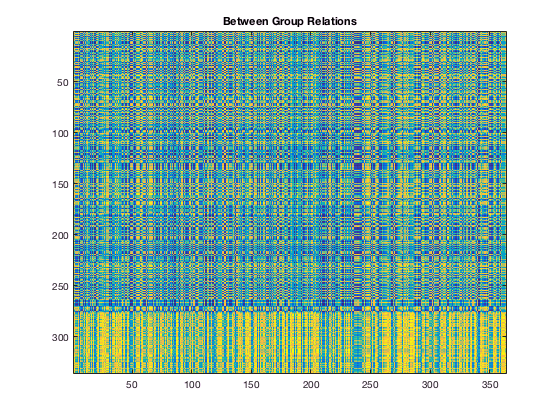

W = CalRelationXY(X, Y, 'gaussian', 'mean');    % Construct W using Gaussian kernel
figure 
imagesc(W);
title('Between Group Relations');

Visualize the Between Group nearest neighbours

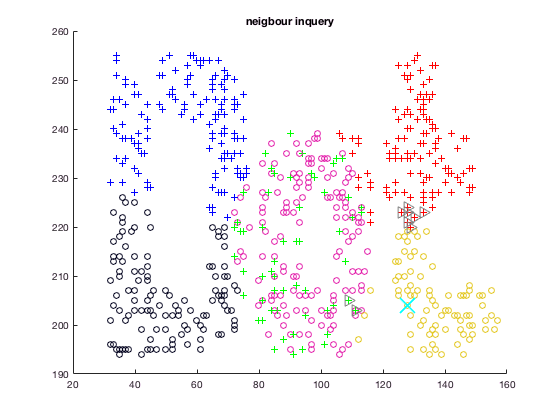

figure
Plotcluster(X', lx, Y', ly);
q = Y(3,:);        % the query point
[knn_idx_for_q, ~] = knnsearch(X, q, 'k', 10);
line(q(:,1),q(:,2),'marker','x','color','c',...
   'markersize',20,'linewidth',2,'linestyle','none')
line(X(knn_idx_for_q,1),X(knn_idx_for_q,2),'color',[.5 .5 .5],'marker','>',...
   'linestyle','none','markersize',10)
title('neigbour inquery');

Build the Linkage matrix C using the shared cross domain sets

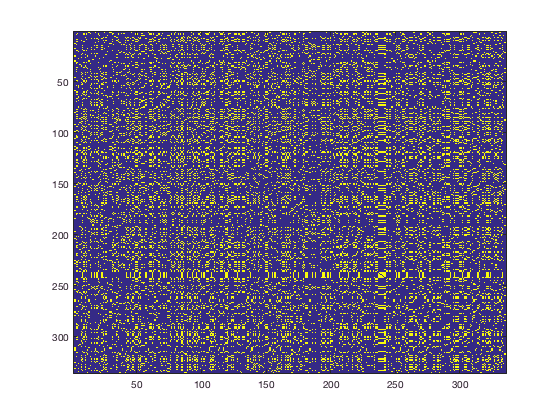

knn =  5;
[knn_for_Y_in_X, ~] = knnsearch(X, Y, 'k', knn);
[M, ~] = size(X);
C = [];
MatrixC = zeros(M);
for ii = 1 : M
    for jj = 1 : (ii - 1)
    if ~isempty(intersect(knn_for_Y_in_X(ii,:), knn_for_Y_in_X(jj,:)))
        C = [C; ii, jj];
        MatrixC(ii, jj) = 1;
    end
    end
end

figure
imagesc(MatrixC | MatrixC.');

Save the data temporarily

save 'tmp.mat' X lx Y ly C W